DATA_FILEPATH = "/Users/siddhantgupta/Documents/MATLAB/ece113dw_project/audio_data";

USE_MELSPECTRUM = true;
USE_MFCC = false;
USE_MFCC_DELTA = false;

% Create datastore
dataset = fullfile(DATA_FILEPATH);

ads = audioDatastore(dataset, ...
    IncludeSubfolders=true, ...
    FileExtensions=".wav", ...
    LabelSource="foldernames");

% Split into train / test

[train,test] = splitEachLabel(ads,0.6,'randomize');

% Extract Features
afe = audioFeatureExtractor( ...
    SampleRate=8000, ...
    FFTLength=512, ...
    Window=hamming(512,"periodic"), ...
    OverlapLength=128, ...
    melSpectrum=USE_MELSPECTRUM, mfcc=USE_MFCC, ...
    mfccDelta=USE_MFCC_DELTA);

num_bands = 32;
if(USE_MELSPECTRUM)
    setExtractorParameters(afe,"melSpectrum",NumBands=num_bands,WindowNormalization=false);
end
if(USE_MFCC)
    setExtractorParameters(afe,"mfcc",NumCoeffs=13);
end

train_d = extract(afe,train);
test_d = extract(afe,test);

% Read in data
%train_d = readall(train_tf);
%test_d = readall(test_tf);

train_d = cat(4,train_d{:});
test_d = cat(4,test_d{:});
[numHops,numBands,numChannels,numFiles] = size(train_d)

numHops = 41

numBands = 32

numChannels = 1

numFiles = 103


% Separate Labels
train_labels = train.Labels;
test_labels = test.Labels;

% Define model
classes = categories(train_labels);
num_classes = numel(classes);
num_filters = 2;

layers = [
    imageInputLayer([numHops,afe.FeatureVectorLength])
    
    convolution2dLayer(3,num_filters,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,2*num_filters,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,4*num_filters,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(num_classes)
    softmaxLayer
    classificationLayer(Classes=classes)];

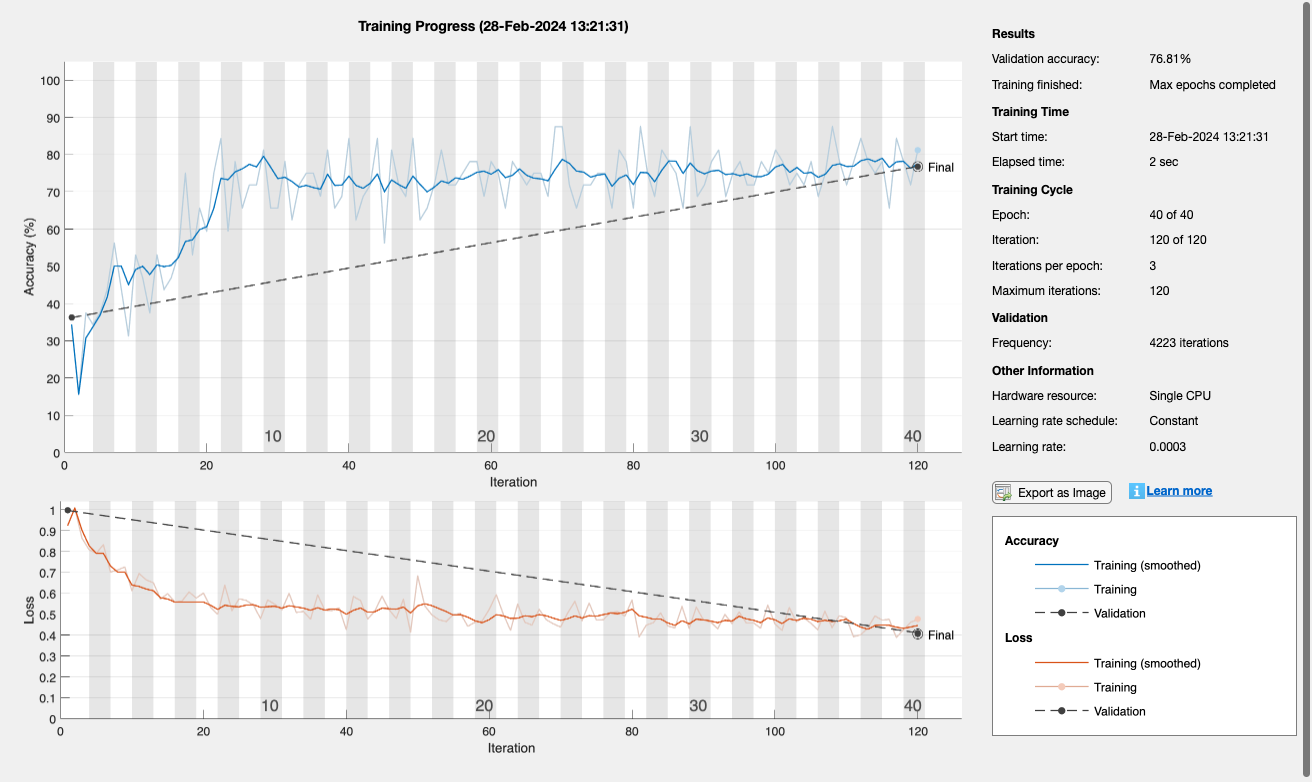

% Train model
miniBatchSize = 32;
validationFrequency = floor(numel(train_d)/miniBatchSize);
options = trainingOptions("adam", ...
    InitialLearnRate=3e-4, ...
    MaxEpochs=40, ...
    MiniBatchSize=miniBatchSize, ...
    Shuffle="every-epoch", ...
    Plots="training-progress", ...
    Verbose=false, ...
    ValidationData={test_d,test_labels}, ...
    ValidationFrequency=validationFrequency);

trainedNet = trainNetwork(train_d,train_labels,layers,options);


trainedNet.Layers(13).Weights

ans = 2×640 single matrix
   -0.0457   -0.0413    0.0142    0.0576   -0.0412    0.0771    0.0382   -0.0687   -0.0517   -0.0137   -0.0010    0.0222   -0.0640    0.1086   -0.0317   -0.0736    0.0817    0.0882    0.0336    0.0527    0.0394    0.0071   -0.1047   -0.0363   -0.0125    0.0707    0.0856    0.0711    0.0947   -0.0427   -0.0357   -0.0014   -0.0407    0.0495   -0.0372   -0.0612   -0.0510   -0.0384   -0.0588   -0.0322    0.0377    0.0062   -0.0162    0.0094    0.0055   -0.0750    0.0882    0.0701   -0.0274    0.0294
    0.0967   -0.0431    0.0134    0.0024    0.0492   -0.0232   -0.0245   -0.0500   -0.1042    0.0404   -0.0297    0.0251   -0.0056   -0.0878   -0.0566    0.0255   -0.0743    0.0509    0.0725   -0.0070   -0.0649   -0.0277    0.0329    0.0097    0.0408    0.0884   -0.0842    0.0745    0.0475   -0.0453   -0.0028    0.0759    0.0458   -0.0188    0.0362   -0.0837   -0.0573    0.0065    0.0336    0.0717    0.0970   -0.0339    0.0835    0.0657   -0.0424   -0.0684   -0.0340   

trainedNet.Layers(6)

ans =   Convolution2DLayer with properties:

              Name: 'conv_2'

   Hyperparameters
        FilterSize: [3 3]
       NumChannels: 2
        NumFilters: 4
            Stride: [1 1]
    DilationFactor: [1 1]
       PaddingMode: 'same'
       PaddingSize: [1 1 1 1]
      PaddingValue: 0

   Learnable Parameters
           Weights: [3×3×2×4 single]
              Bias: [1×1×4 single]

  Show all properties


test_pred = classify(trainedNet,test_d);
validationError = mean(test_pred ~= test_labels);
train_pred = classify(trainedNet,train_d);
trainError = mean(train_pred ~= train_labels);

disp(["Training error: " + trainError*100 + " %";"Validation error: " + validationError*100 + " %"])

    "Training error: 23.301 %"
    "Validation error: 23.1884 %"



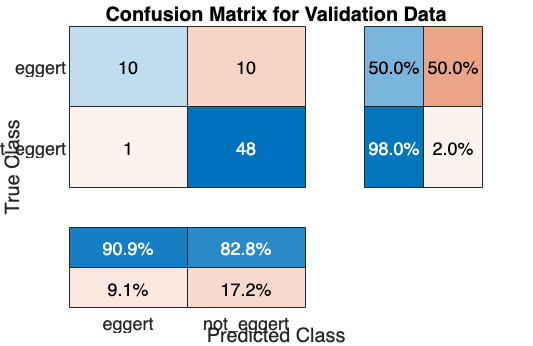

figure(Units="normalized",Position=[0.2,0.2,0.5,0.5]);
cm = confusionchart(test_labels,test_pred, ...
    Title="Confusion Matrix for Validation Data", ...
    ColumnSummary="column-normalized",RowSummary="row-normalized");